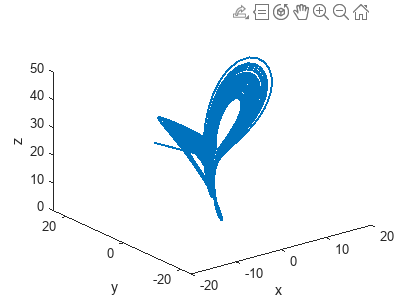

clc;
close all;
clear;

% Lorenz attractor parameters
sigma = 10;
beta = 8/3;
rho = 28;

% Lorenz attractor equations
dxdt = @(t,x) [sigma*(x(2)-x(1)); x(1)*(rho-x(3))-x(2); x(1)*x(2)-beta*x(3)];

% Initial conditions
x0 = [-8; 8; 27];

% Time interval
tspan = [0 50];

% Solve the ODE using MATLAB's ode45 solver
[t,x] = ode45(dxdt, tspan, x0);

% Plot the Lorenz attractor
plot3(x(:,1), x(:,2), x(:,3), 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');